# (M E 325 Exam 1 Problem 4

### Group 6

#### Parker Wilson, Preston Witte, Mike Lawlor, Justin Merkel

A machine component that has a rectangular cross-section (3.00” x 0.75”) has a 0.25” edge notch machined into it as shown below. The loading on the part is cyclical and in the first half cycle of stress, a 1200 lb axial force and a bending moment of 2000 in-lb act on the part (then bending moment in the first half cycle causes tension on the top surface of the part). In the second half of the stress cycle, the axial load drops to 0 and the bending moment reverses. The part is machined and operates in an environment with a temperature that is 200o F. The required reliability of the material properties is 95 percent. There are no conditions that would warrant application of a Marin factor for ”miscellaneous effects” on the fatigue strength. The part is designed for 5 ×106 stress cycles.

**FOR THIS ANLYSIS WE ARE IGNORING THE MARIN FACTORS FOR ALUMINIUM**

## Determine

- The factor of safey against yielding using the load line and DET faulure envelope

- The factor of safety against fatigue (goodman line)

#### Specimen Loading and relevant data:

            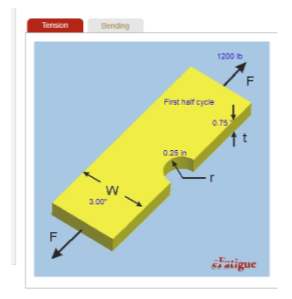                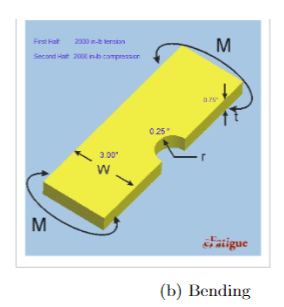

`•`Sut = 90 kpsi

`•`Sy = 60 kpsi

`•`Sf at 1000 cycles = 0.85Sut

`•`Sf at 50 ×10^7 = 20kpsi

Fx1 = 1200 ;                 %lb
Mx1 = 2000   ;                %in-lb
r = 0.25      ;              %in
W = 3      ;                 %in
t = 0.75       ;             %in

#### Material Properties:

The material from which the bar is fabricated has an ultimate tensile strength, $S_{\textrm{ut}}$, of 90 kpsi and the yield strength, $S_y$, of the material is 60 kpsi.

S_ultimate = 90;
S_yield = 60;
Sf_1000 = 0.85 * S_ultimate; %kpsi
Sf_50_10_7 = 20;             %kpsi

#### 2nd Half of loading cycle

Fx2 = 0; %lb
Mx2 = -2000; %in-lb

The types of loading experienced by the specimen are axial and bending

Determine stress concentration factors for each type of loading from eFatigue website.

Axial:

K_t_axial = 2.42;

Bending:

K_t_bending = 2.28;

Calculate Notch sensitivity factors for each type of loading:

First, neubers numbers are needed

neuber_axial = 0.246-3.08*(10^-3)*S_ultimate+1.51*(10^-5)*S_ultimate^2-2.67*(10^-8)*S_ultimate^3;
neuber_bending = 0.246-3.08*(10^-3)*S_ultimate+1.51*(10^-5)*S_ultimate^2-2.67*(10^-8)*S_ultimate^3;

Notch sensitivity factors

q_axial = 1/(1 + (neuber_axial/sqrt(r)));
q_bending = 1/(1 + (neuber_bending/sqrt(r)));

Calculate fatigue stress concentration factors

K_f_axial = q_axial*(K_t_axial-1)+1;
K_f_bending = q_bending*(K_t_bending-1)+1;

Adjust stresses with stress concentration factors for 1st loading:

Base = W-r;                      % base of the rectagnular cross section considered
Height = t;                      % height of the rectangular cross section considered
A = (Base*Height);               % area of the bar where max stress occurs
Ix = (Base*(Height^3))/12;   %second moment of area for the above cross section
stress_x_1 = K_f_axial*(Fx1/(A)) + K_f_bending*(Mx1*(t/2)/(Ix));

Adjust stresses with stress concentration factors for 2nd loading:

stress_x_2 = K_f_bending*(Mx2*(t/2)/(Ix));  % no axial load, compression purely from bending moment

Developing state of stress and finding principal stresses

sigma_x = stress_x_1;  %because of the tension and orientation of the bending moment, there are no other stresses other than in the x direction
sigma_y = 0;
tau_xy = 0;
theta1 = atand(tau_xy/(sigma_x-sigma_y));

sigma_x_p = sigma_x*(cos(theta1).^2);


Developing the DET Failure Envelope

theta = linspace(0,2*pi);
rho = S_yield .* sqrt(1./(1-sin(theta).*cos(theta)));

[x,y1] = pol2cart(theta,rho);

hold on

Plotting All lines and Editing Axes/Labels

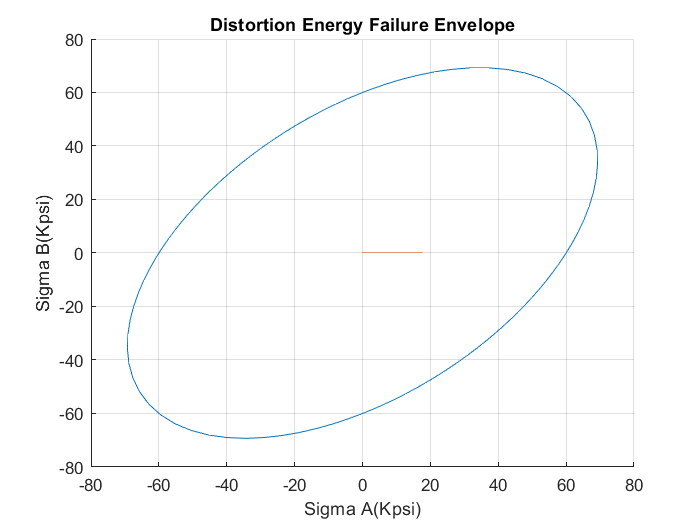

plot(x,y1,[0,sigma_x/1000],[sigma_y,sigma_y])
title('Distortion Energy Failure Envelope')
xlabel('Sigma A(Kpsi)')
ylabel('Sigma B(Kpsi)')
grid on

figure;


Calculating the Factor of Safety According to Distortion Energy Theory

FS_DET=(S_yield/(sigma_x/1000))

FS_DET = 3.3808

Calculate mean and alternating stresses

stress_a = (stress_x_1-stress_x_2)/2;
stress_m = (stress_x_1+stress_x_2)/2;

Calculate mean and alternating principle stresses:

stress_m_p_1 = stress_m/2 + sqrt((stress_m/2)^2);
stress_m_p_3 = stress_m/2 - sqrt((stress_m/2)^2);
stress_a_p_1 = stress_a/2 + sqrt((stress_a/2)^2);
stress_a_p_3 = stress_a/2 - sqrt((stress_a/2)^2);

Calculate mean and alternating von Mises stresses:

von_mises_m = sqrt(stress_m_p_1^2 + stress_m_p_3^2 - stress_m_p_1*stress_m_p_3);
von_mises_a = sqrt(stress_a_p_1^2 + stress_a_p_3^2 - stress_a_p_1*stress_a_p_3);

Creating The Goodman Line

Goodman=-Sf_50_10_7*x/S_ultimate+Sf_50_10_7

Goodman =     6.6667    6.2513    5.8561    5.4902    5.1656    4.8975    4.7049    4.6099    4.6365    4.8087    5.1469    5.6638    6.3609    7.2260    8.2342    9.3513   10.5384   11.7581   12.9777   14.1718   15.3229   16.4198   17.4571   18.4334   19.3499   20.2099   21.0172   21.7765   22.4923   23.1692   23.8115   24.4231   25.0079   25.5691   26.1099   26.6331   27.1413   27.6369   28.1218   28.5980   29.0671   29.5307   29.9901   30.4461   30.8995   31.3507   31.7995   32.2452   32.6863   33.1202


Loadline=stress_a*x/stress_m

Loadline = 	1.0e+03 *

    1.5726    1.6216    1.6682    1.7114    1.7497    1.7813    1.8040    1.8152    1.8121    1.7917    1.7519    1.6909    1.6087    1.5066    1.3877    1.2560    1.1160    0.9721    0.8283    0.6874    0.5516    0.4223    0.2999    0.1848    0.0767   -0.0248   -0.1200   -0.2095   -0.2940   -0.3738   -0.4495   -0.5217   -0.5907   -0.6569   -0.7206   -0.7824   -0.8423   -0.9007   -0.9579   -1.0141   -1.0694   -1.1241   -1.1783   -1.2321   -1.2856   -1.3388   -1.3917   -1.4443   -1.4963   -1.5475


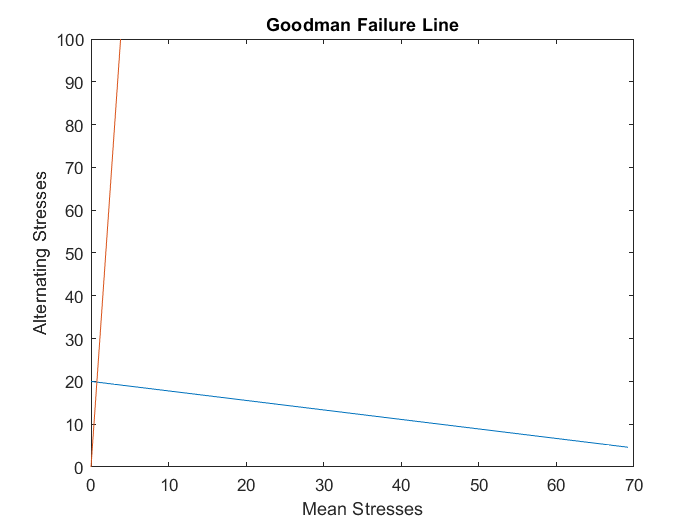

plot(x,Goodman,x,Loadline)
xlabel('Mean Stresses')
ylabel('Alternating Stresses')
title('Goodman Failure Line')
xlim([0 70])
ylim([0 100])

figure;


Goodman Factor of Safety Formula

FS_Goodman=(((stress_a/1000)/Sf_50_10_7)+(stress_m/1000)/S_ultimate)^(-1)

FS_Goodman = 1.1601